Console preparation

clc;
close all; 
warning('off', 'all');

Import the data for the step response of the fan

open('251125stepresponse.fig'); 
a = get(gca,'Children');  
obj_r = a(2);  
x_sr_fan = obj_r.XData;
y_sr_fan = obj_r.YData; % Drehzahl [RPM]
close(gcf);

open('251125height_ramp.fig'); 
b = get(gca,'Children');  
obj_r_alpha2 = b(2);  
x_constant_w = obj_r_alpha2.XData;
y_constant_w = obj_r_alpha2.YData; 
close(gcf);

Cut out only the last 60 s of the data which is the size of the actual window in the scope

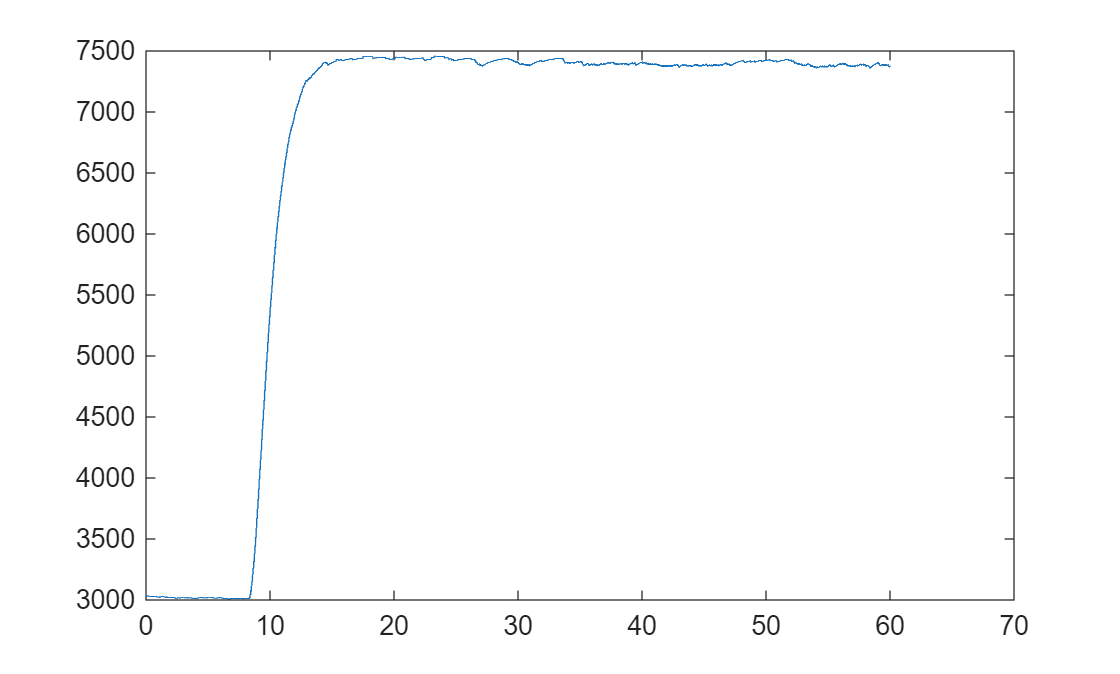

time_limit_sr = max(x_sr_fan) - 60; 
idx_sr = x_sr_fan >= time_limit_sr;
x_sr_fan = x_sr_fan(idx_sr);
y_sr_fan = y_sr_fan(idx_sr);
t_r = x_sr_fan(:);
Ts_r = mean(diff(t_r));


time_limit_cw = max(x_constant_w)-60; 
idx_cw = x_constant_w >= time_limit_cw;
x_constant_w = x_constant_w(idx_cw);
y_constant_w = y_constant_w(idx_cw);
t_cw = x_constant_w(:);        % time vector (column)
Ts_cw = mean(diff(t_cw));      % average sample time

plot(t_r,y_sr_fan);

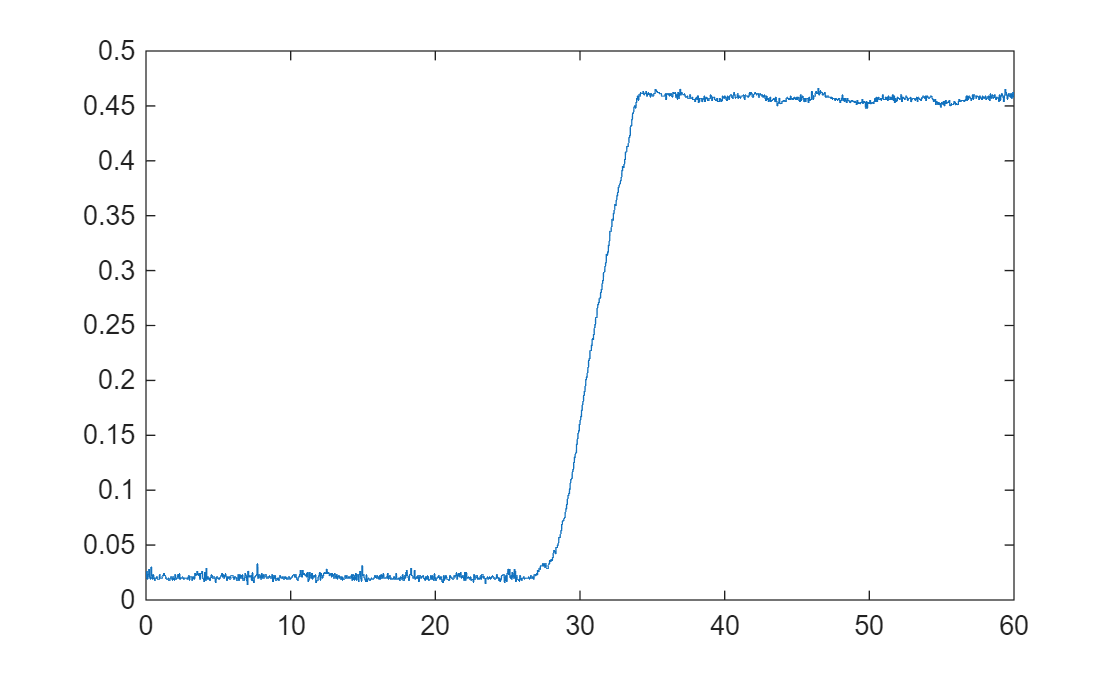

plot(t_cw,y_constant_w);

avg_rpm_constant = (4246 + 4200) / 2

avg_rpm_constant = 4223

w_constant = avg_rpm_constant

w_constant = 4223

Variable values

y_rotations = y_sr_fan;
kl = 5.5e-5;
m = 2.7e-3;
Ab = 1.257e-3;
Atube = 1.452e-3;
Agap = Atube - Ab;
g = 9.81;
rotations_at_ss = 4218; %rpm % 9.35 constant
w_bar = rotations_at_ss

w_bar = 4218

duty_cycle =    [0      5       7.5     10      20      40      50];  % duty cycle
rpm     =       [3020   3750    4000    4300    5450    7200    8000]; 
% rpm     = [3024 3622 5308 6150 7700 7770 7500]; old
w_duty_cycle = rpm

w_duty_cycle =         3020        3750        4000        4300        5450        7200        8000


Calculation of the coefficients 

% 9.35 oben

% 8.75 unten

alpha1 = sqrt(g)/w_bar

alpha1 = 7.4255e-04

alpha3 = g

alpha3 = 9.8100

z_dot = (0.449-0.042)/(33.725-28.335)

z_dot = 0.0755

u = duty_cycle %(duty_cycle / 100) * 5

u =          0    5.0000    7.5000   10.0000   20.0000   40.0000   50.0000


alpha2 = (alpha1 * w_constant - sqrt(g))/z_dot

alpha2 = 0.0492

alpha2 = alpha1*w_bar/z_dot - sqrt(g)/z_dot 

alpha2 = 0

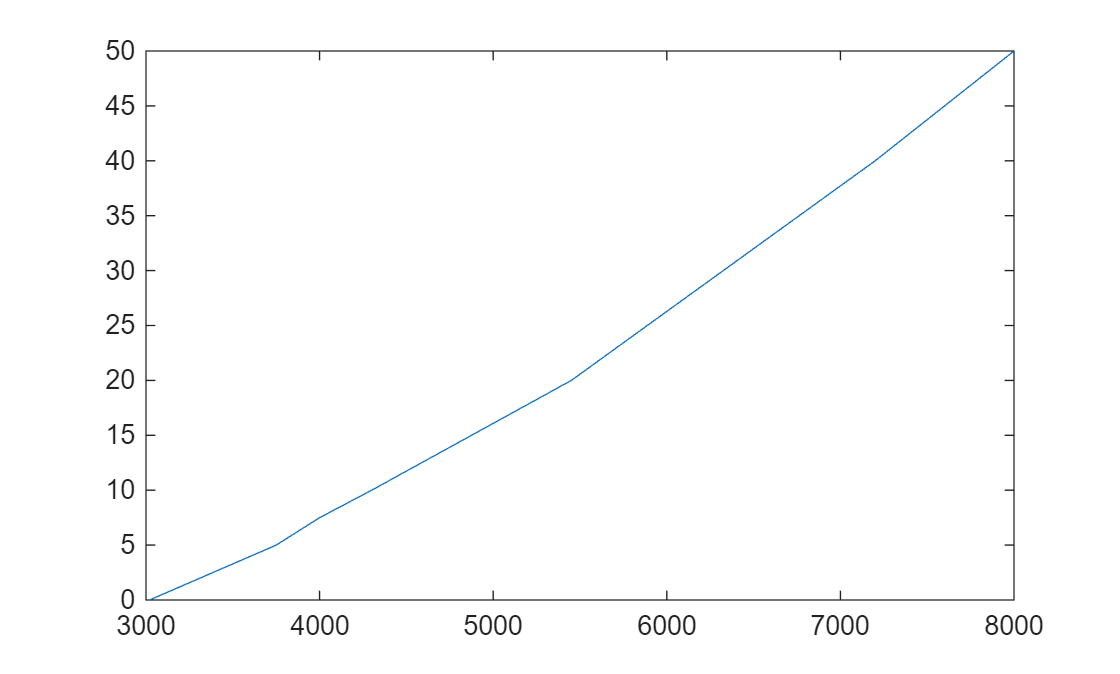

plot(w_duty_cycle,u);

polyfit_of_w = polyfit(w_duty_cycle, u, 1);
m = polyfit_of_w(1);
d = polyfit_of_w(2);
ktau_from_rpm_ramp = 1/m

ktau_from_rpm_ramp = 98.4912

u0 = (d / 100) * 5

u0 = -1.6441

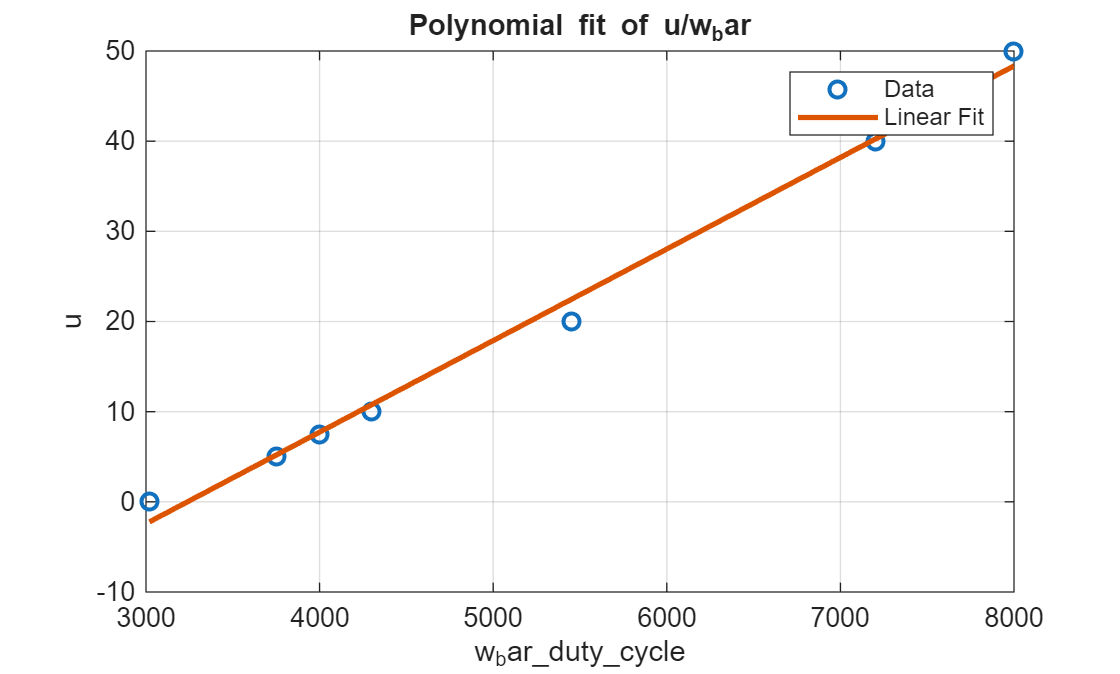

w_fit = linspace(min(w_duty_cycle), max(w_duty_cycle), 200);
u_fit = m * w_fit + d;
figure;
plot(w_duty_cycle, u, 'o', 'MarkerSize', 6, 'LineWidth', 1.5); hold on;
plot(w_fit, u_fit, 'LineWidth', 2);
grid on;

xlabel('w_bar\_duty\_cycle');
ylabel('u');
title('Polynomial fit of u/w_bar');
legend('Data', 'Linear Fit');

y_baseline = mean(y_rotations(1:10)); 
y_shifted = y_rotations(:) - y_baseline; 
U_step = 9.5%(9.5/100)*5

U_step = 9.5000

u = ones(length(y_rotations), 1) * U_step; 
u = u(:);
data_obj = iddata(y_shifted, u, Ts_r); 
sys_tfest_raw = tfest(data_obj, 1, 0);
[num, den] = tfdata(sys_tfest_raw, 'v');
A = num(end); 
a = den(end); 
tau_estimated = 10.35 - 8.385

tau_estimated = 1.9650

ktau_estimated = A / a

ktau_estimated = 480.1299

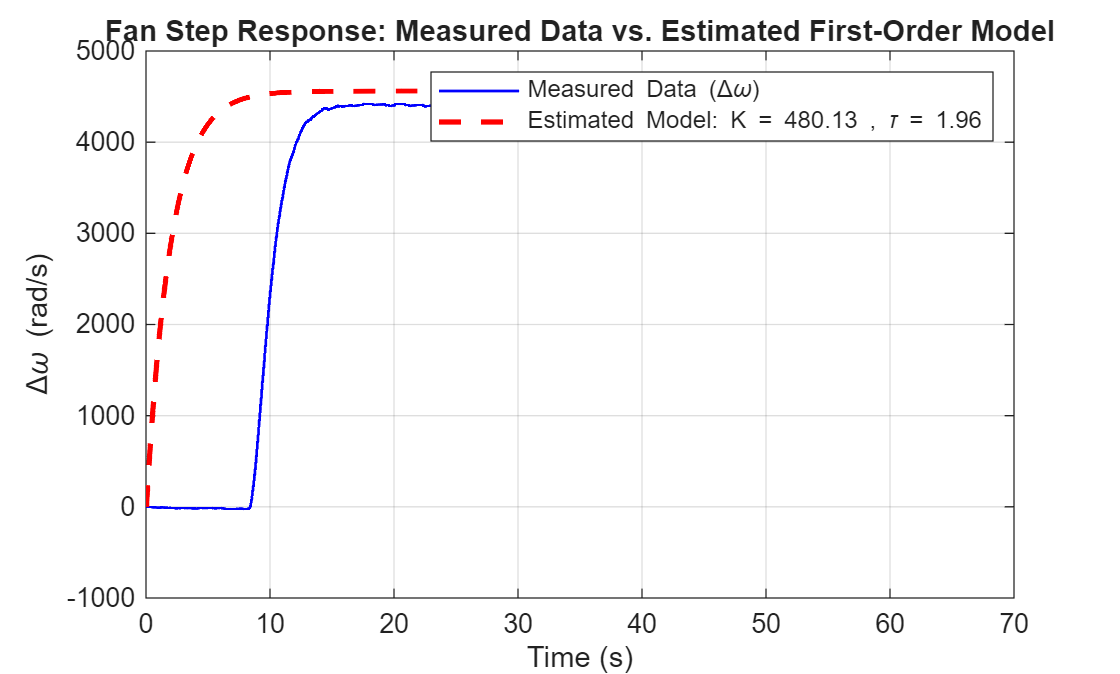

sys_pt1_sim = tf(ktau_estimated, [tau_estimated 1]);

t_r = x_sr_fan(:); 

[y_sim, t_sim] = step(sys_pt1_sim, t_r); 
y_sim_scaled = y_sim * U_step;

figure;
plot(t_r, y_shifted, 'b', 'LineWidth', 1); hold on;
plot(t_sim, y_sim_scaled, 'r--', 'LineWidth', 2);
grid on;

xlabel('Time (s)');
ylabel('\Delta\omega (rad/s)');
title('Fan Step Response: Measured Data vs. Estimated First-Order Model');

% --- CORRECTED LEGEND LINE ---
legend_str_k = sprintf('K = %.2f', ktau_estimated);
legend_str_tau = sprintf('\\tau = %.2f', tau_estimated);
legend('Measured Data (\Delta\omega)', ['Estimated Model: ' legend_str_k ' , ' legend_str_tau]);

fprintf(['alpha1 = %.4f;\n', ...
         'alpha2 = %.4f;\n', ...
         'alpha3 = %.4f;\n', ...
         'tau_estimated = %.4f;\n'], ...
         alpha1, alpha2, alpha3, tau_omega);

alpha1 = 0.0007;
alpha2 = 0.0000;
alpha3 = 9.8100;
tau_estimated = 1.4000;


fprintf(['alpha1 = %g;\n', ...
         'alpha2 = %g;\n', ...
         'alpha3 = %g;\n', ...
         '%% Lüfter Parameter \n', ...
         'tau_omega = %g;                       %% [s] Zeitkonstante PT1 (aus Messung)\n', ...
         'k_omega = %g;                %% [rpm/%%] K Wert PT1 (aus Messung)\n'], ...
         alpha1, alpha2, alpha3, tau_omega, ktau_from_rpm_ramp);

alpha1 = 0.000742554;
alpha2 = 0;
alpha3 = 9.81;
% Lüfter Parameter 
tau_omega = 1.4;                       % [s] Zeitkonstante PT1 (aus Messung)
k_omega = 98.4912;                % [rpm/%] K Wert PT1 (aus Messung)
